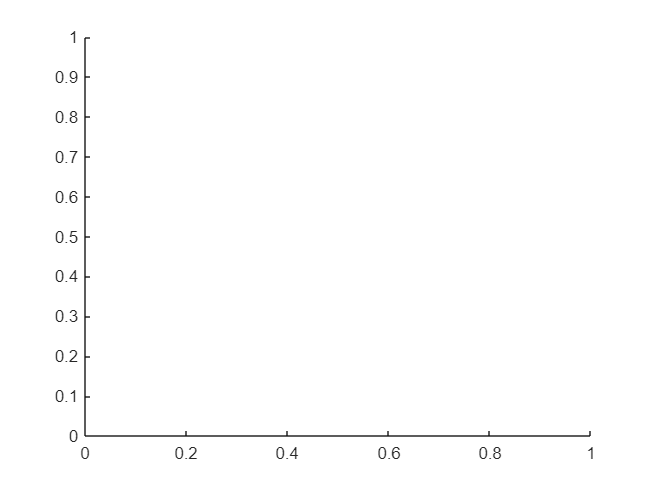

clear all
clc
hold on

%Definición parámetros, en este caso para el PWP201
Voc=16.799;
Isc=1.0317;
Imp=0.92550;
Vmp=12.4929;
Ns=36;
kI=0;
kv=0;
G=1000;
T=45;
Gd=1000;
Ie= transpose(xlsread('PWP201.xlsx','C3:C25'));
Ve= transpose(xlsread('PWP201.xlsx','B3:B25'));
%constantes física
q=1.60218*10^(-19);
K=1.380649*10^(-23);
%Calculo Vth por Ns
Vth=Ns*K*(T+273.15)/q;
%constantes física
q=1.60218*10^(-19);
K=1.380649*10^(-23);
%Calculo Vth por Ns
Vth=Ns*K*(T+273.15)/q;
%Valores iniciales
Iph1=Isc; 
n1=1.1;
Io1=Isc/(exp(Voc/(n1*Vth))-1);
Rs1=(Voc-Vmp)/Imp;
Rsh1=Vmp/(Isc-Imp);
err=10;
iter=0;
%definición de funciones y la jacobiana del sistema
syms Io Rs Rsh n Iph
f1=Io/(n*Vth)*exp((Vmp+Imp*Rs)/(n*Vth))*(1-Imp*Rs/Vmp)-Imp/Vmp*(1+Rs/Rsh)+1/Rsh;
f2= Rsh-(n*Vth*Rs*exp(-Isc*Rs/(n*Vth)))/(Io*(Rsh-Rs));
f3=-Isc+Iph-Io*(exp((Isc*Rs)/(n*Vth))-1)-(Isc*Rs)/Rsh;
f4=Iph-Io*(exp(Voc/(n*Vth))-1)-Voc/Rsh;
f5=-Imp+Iph-Io*(exp((Vmp+Imp*Rs)/(n*Vth))-1)-(Vmp+Imp*Rs)/Rsh;
F=[f1 f2 f3 f4 f5]; 
v=[Io Rs Rsh n Iph];
J=jacobian(F,v);
%sistema a resolver
fa=@(Io,Rs,Rsh,n,Iph)Io/(n*Vth)*exp((Vmp+Imp*Rs)/(n*Vth))*(1-Imp*Rs/Vmp)-Imp/Vmp*(1+Rs/Rsh)+1/Rsh;
fb=@(Io,Rs,Rsh,n,Iph) Rsh-(n*Vth*Rs*exp(-(Isc*Rs)/(n*Vth)))/(Io*(Rsh-Rs));
fc=@(Io,Rs,Rsh,n,Iph)-Isc+Iph-Io*(exp((Isc*Rs)/(n*Vth))-1)-(Isc*Rs)/Rsh;
fd=@(Io,Rs,Rsh,n,Iph)Iph-Io*(exp(Voc/(n*Vth))-1)-Voc/Rsh;
fe=@(Io,Rs,Rsh,n,Iph)-Imp+Iph-Io*(exp((Vmp+Imp*Rs)/(n*Vth))-1)-(Vmp+Imp*Rs)/Rsh;
%Vector con la estimación inicial de los parámetros
V1=[Io1,Rs1,Rsh1,n1,Iph1];
while(err>0.0001)
V0=V1;
jaco=subs(J,v,V0);
jaco=double(jaco);
f=[fa(V0(1),V0(2),V0(3),V0(4),V0(5)),fb(V0(1),V0(2),V0(3),V0(4),V0(5)),fc(V0(1),V0(2),V0(3),V0(4),V0(5)),fd(V0(1),V0(2),V0(3),V0(4),V0(5)),fe(V0(1),V0(2),V0(3),V0(4),V0(5))];
V1=V0-transpose((jaco)\transpose(f));
err=100*norm(V1-V0)/norm(V1); 
iter=iter+1;
end
%mostrar resultados
iter

iter = 9

Io1=V1(1)

Io1 = 3.3358e-07

Rs1=V1(2)

Rs1 = 1.7680

Rsh1=V1(3)

Rsh1 = 1.0865e+03

n1=V1(4)

n1 = 1.1399

Iph1=V1(5)

Iph1 = 1.0334

%calculo puntos curva I-V con los parámetros obtenidos
for i=1:length(Ve)
    clear I    
    syms I
    eqn1=I==Iph1-Io1*(exp((Ve(i)+I*Rs1)/(n1*Vth))-1)-(Ve(i)+I*Rs1)/Rsh1;
    Ik=vpasolve(eqn1,I);
    Isol(i)=double(Ik);
end
%Cálculo RMSE
    RMSE=rmse(Isol,Ie)/Isc*100

RMSE = 1.2827